An implementation of the variational stochastic gradient descent algorithm for noisy gradient evaluations.

Added reflective boundaries to allow constrained optimization 

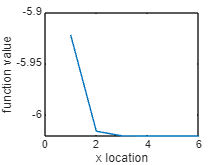

[x,Fx,xv,fv] = optim.RecursiveGrid(@(x) forr(x),6,20,0,1);

figure
plot(fv)

xlabel('x location')
ylabel('function value')

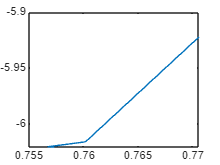


figure
plot(xv,fv.'.')

function [y,dy] = forr(x)

y = ((6*x-2).^2).*sin(12*x-4);
dy =12*(6*x-2).*(sin(12*x-4) + (6*x-2).*cos(12*x-4)) + normrnd(0*x,1);

end